# Fuzzy Systems - Assignment #2 - Arian Tashakkor - 40023494

## Problem 1

Composition of two relations is done exactly like matrix multiplication with the exception that we replace "$\times$" with a T-norm and "$+$" with $max$. The result of the $R\circ S$ in both cases below is a 2-by-4 relation matrix mapping $x$ to $z$.

### A. Max-min composition $R\circ S$:

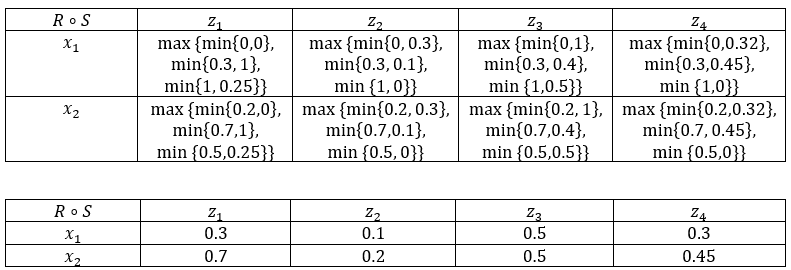

### B. Max-product composition $R\circ S$:

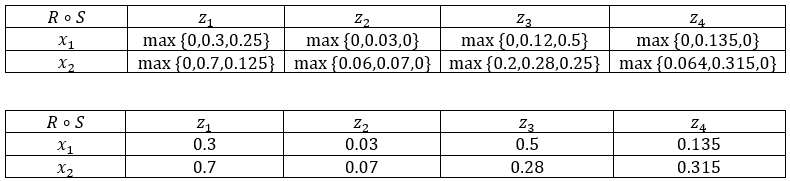

## Problem 2

Assuming T-norm T, S-norm S and complement N:

### A. (x is close and x is not slow) or x is positive


$$S(T(\mu_C, N(\mu_S)), \mu_P)$$


### B. (x is positive or x is slow) and x is close


$$T(S(\mu_P, \mu_S), \mu_C)$$


### C. (x is not slow and x is not close) or (x is not positive or x is slow)


$$S(T(N(\mu_S), N(\mu_C)), S(N(\mu_P), \mu_S))$$


### D. ((x is not slow and x is close) or (x is not positive or x is not slow)) and x is positive


$$T(S(T(N(\mu_S), \mu_C), S(N(\mu_P), N(\mu_S)), \mu_P)$$


## Problem 3

We can define the membership functions mathematically as follows:


$$\mu_A(x) = \begin{cases} 1-\left|\frac{x-4}{4}\right|, 0\le x \le 8 \\ 0, otherwise \end{cases}$$



$$\mu_{A'}(x) = \begin{cases} 1-\left|\frac{x-8}{4}\right|, 4\le x \le 12 \\ 0, otherwise \end{cases}$$



$$\mu_B(y) = \begin{cases} 1-\left|\frac{y}{4}\right|, -4\le y \le 4 \\ 0, otherwise \end{cases}$$



$$\mu_{B'}(y) = \begin{cases} 1-\left|\frac{y-6}{4}\right|, 2\le y \le 10 \\ 0, otherwise \end{cases}$$



$$\mu_C(z) = \begin{cases} 1-\left|\frac{z+4}{4}\right|, -8\le z \le 0 \\ 0, otherwise \end{cases}$$


And the fuzzy rule is:

"if x is A and y is B then z is C"

We will first calculate the firing strength of A and B:

For $A$ and $A'$ we have:


$$\omega_A = S(A, A') = \max\{\min\{\mu_A(x), \mu_{A'}(x)\}\}$$


$A$ and $A'$ are both non-zero only for $4\le x \le 8$ and the intersection of $\mu_A$ and $\mu_{A'}$ in this interval determines $\omega_A$ so we solve $\mu_A(x) = \mu_{A'}(x)
$:

$1 - \frac{x-4}{4} = 1 + \frac{x-8}{4} \rightarrow x-4 = 8-x \rightarrow x = 6, \mu_A(x) = \mu_{A'}(x) = 0.5 = \omega_A$ ,

similarly for the $B$ and $B'$ we have:


$$\omega_B = S(B, B') = \max\{\min\{mu_B(y), \mu_{B'}(y)\}\}$$


$B$ and $B'$ are both non-zero only for $2 \le y \le 4$ and the intersection of $\mu_B$ and $\mu_{B'}$ in this interval determines $\omega_B$:

$1 - \frac{y}{4} = 1 + \frac{y-6}{4} \rightarrow y = 6 - y \rightarrow y = 3 \rightarrow \mu_B(y) = \mu_{B'}(y) = 0.75 = \omega_B$.

With both firing strengths calculated, we are ready to construct $\mu_{C'}$:


$$\mu_{C'} = \min\{\omega_A, \omega_B, \mu_C\} = \min\{0.5, \mu_C\}$$


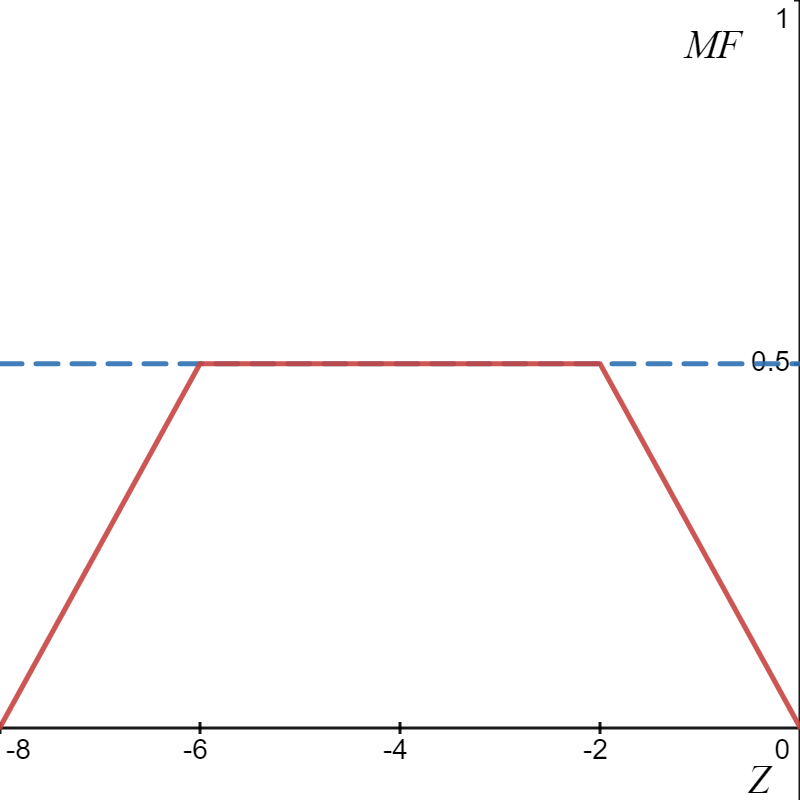

## Problem 4

First we will define our fuzzy sets as per the instructions provided within the problem statement:

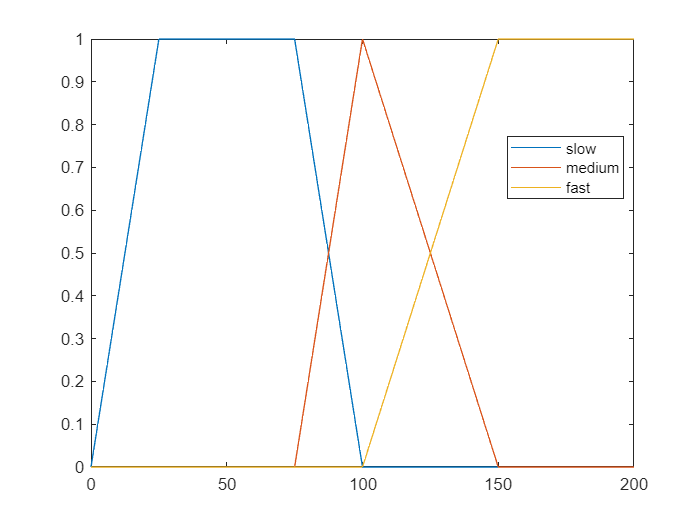

domain4 = 0:0.5:200;
slow = trapmf(domain4, [0, 25, 75, 100]);
medium = trimf(domain4, [75, 100, 150]);
fast = trapmf(domain4, [100, 150, 200, 200]);
plot(domain4, slow, domain4, medium, domain4, fast);
legend("slow", "medium", "fast", "Location","best");
hold off

Now we can define our compound fuzzy statements and plot them:

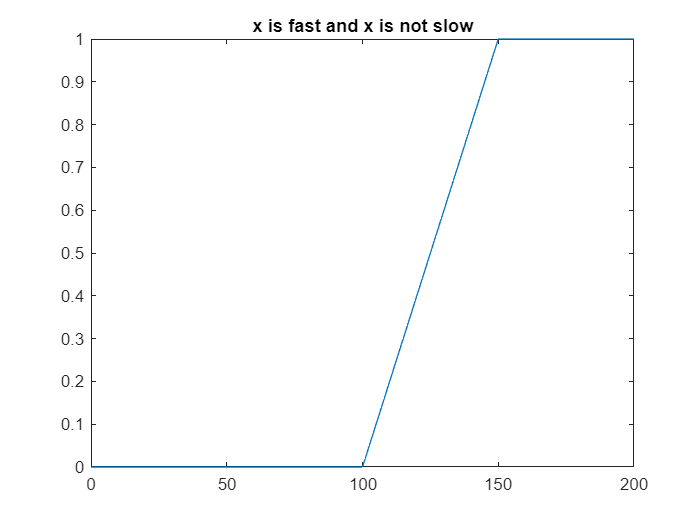

fp1 = min(fast, 1 - slow);
plot(domain4, fp1);
title("x is fast and x is not slow");
hold off

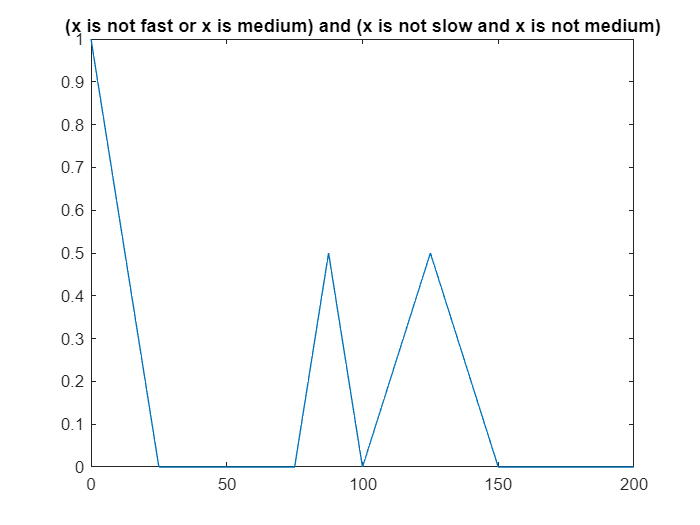

fp2 = min(max(1 - fast, medium), min(1 - slow, 1 - medium));
plot(domain4, fp2);
title("(x is not fast or x is medium) and (x is not slow and x is not medium)");
hold off

## Problem 5

Similar to Problem 4, we will first define our fuzzy sets as instructed by the problem statement:

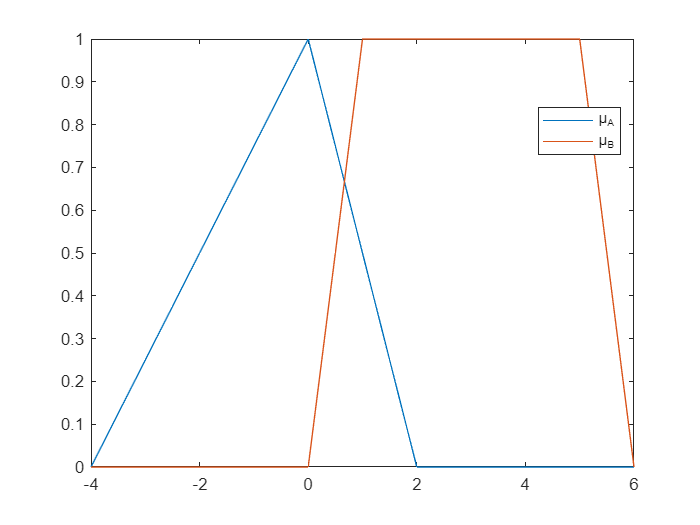

domain5 = -4:0.5:6;
A_5 = trimf(domain5, [-4, 0, 2]);
B_5 = trapmf(domain5, [0, 1, 5, 6]);
plot(domain5, A_5, domain5, B_5);
legend("\mu_A", "\mu_B", "Location","best");
hold off

We can now plot the results of the following compound fuzzy statements:

### A. x is A and y is B

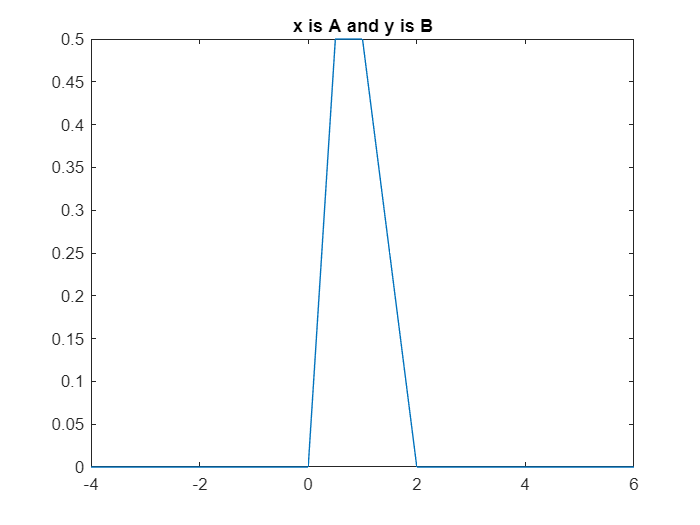

fpa = min(A_5, B_5);
plot(domain5, fpa);
title("x is A and y is B");
hold off

### B. x is A or y is B

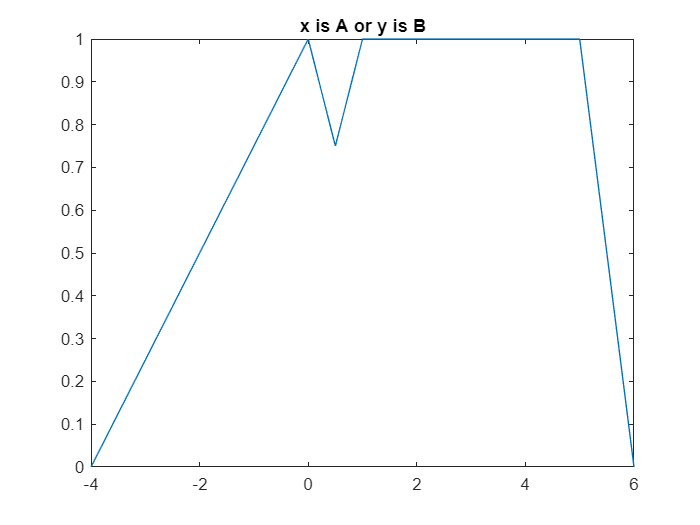

fpb = max(A_5, B_5);
plot(domain5, fpb);
title("x is A or y is B");
hold off

### C. x is not A or y is B

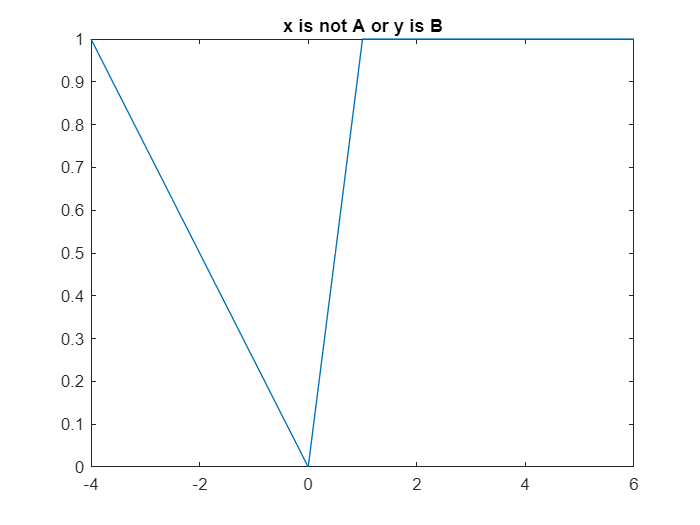

fbc = max(1 - A_5, B_5);
plot(domain5, fbc);
title("x is not A or y is B");
hold off

### D. x is not A or y is not B

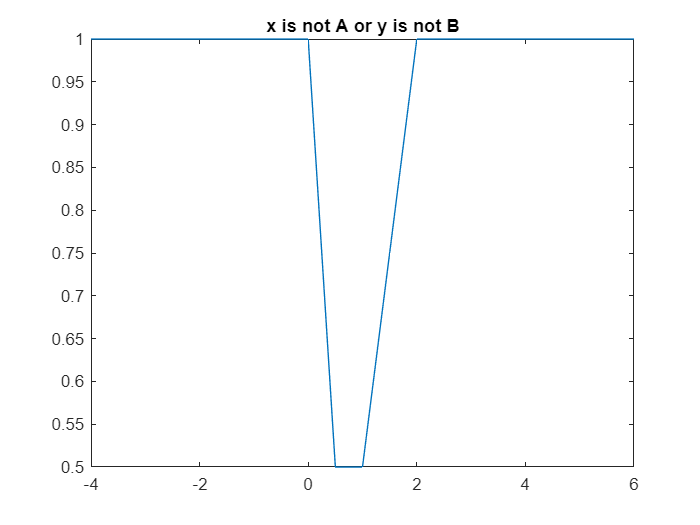

fbd = max(1 - A_5, 1 - B_5);
plot(domain5, fbd);
title("x is not A or y is not B");
hold off

## Problem 6

First we will define A and B according the specifications given in the problem statement:

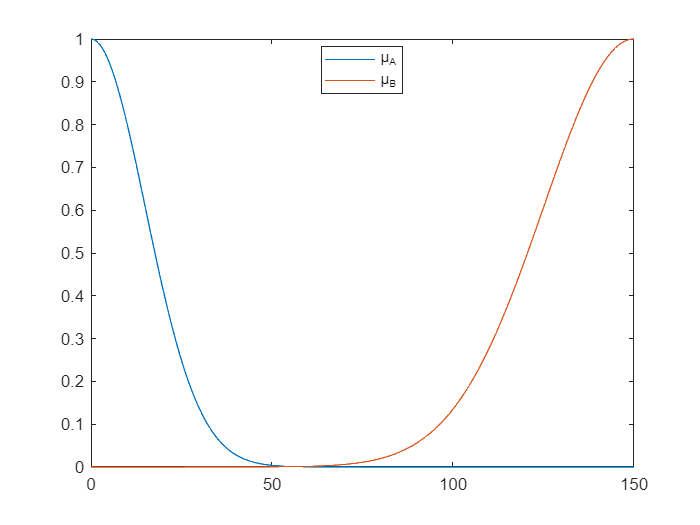

domain6 = 0:0.5:150;
A_6 = gaussmf(domain6, [15, 0]);
B_6 = gaussmf(domain6, [25, 150]);
plot(domain6, A_6, domain6, B_6);
legend("\mu_A", "\mu_B", "Location","best");
hold off

Now we can use the linguisitic hedges to alter these fuzzy sets:

### A. somewhat A

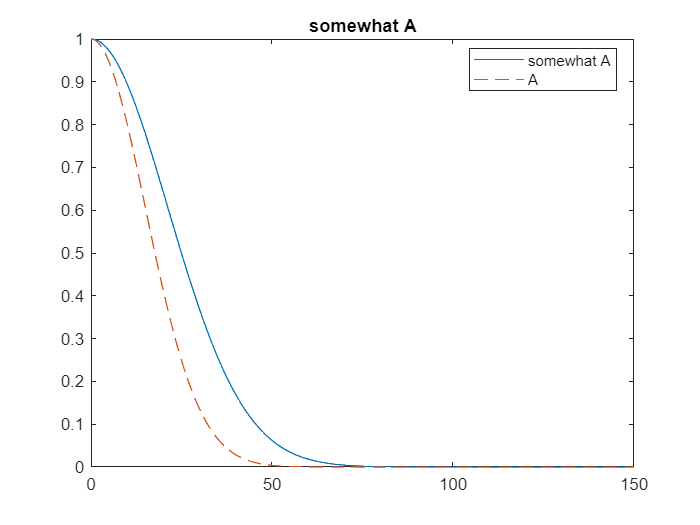

plot(domain6, A_6.^0.5, domain6, A_6, "--");
title("somewhat A");
legend("somewhat A", "A", "Location","best")
hold off

### B. more or less B

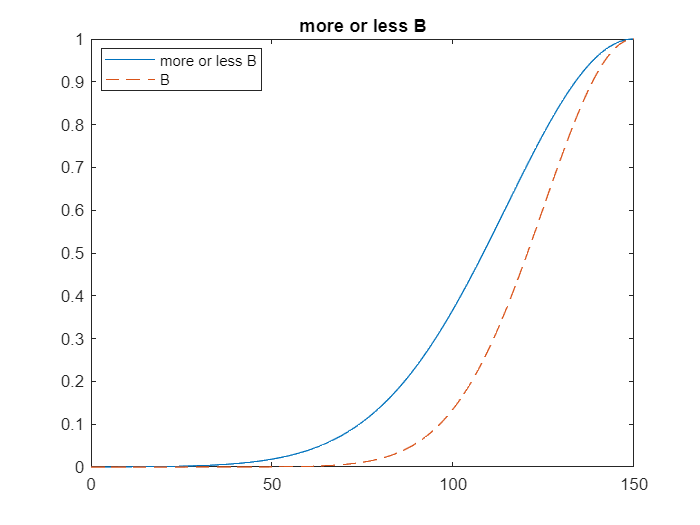

plot(domain6, B_6.^0.5, domain6, B_6, "--");
title("more or less B");
legend("more or less B", "B", "Location","best");
hold off

### C. very very B

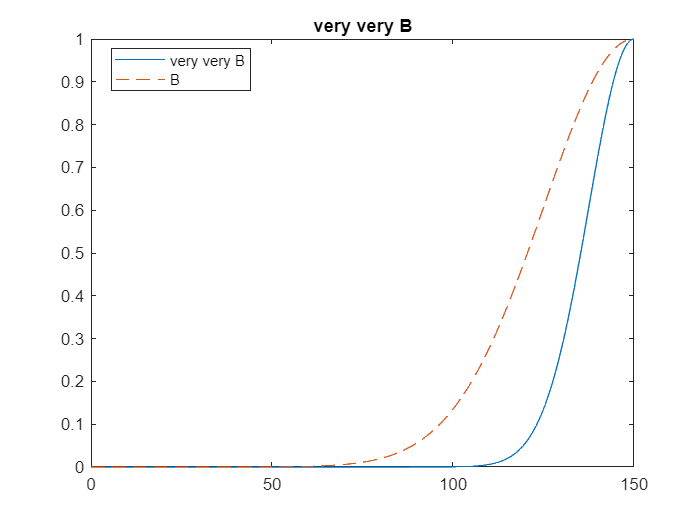

plot(domain6, B_6.^4, domain6, B_6, "--");
title("very very B");
legend("very very B", "B", "Location","best");
hold off